# **ETAPA DE ESTIMACION CON VARIOS MODELOS**

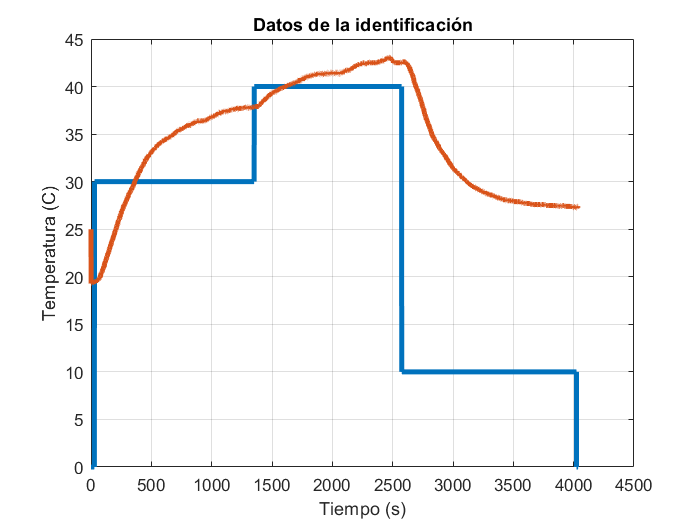

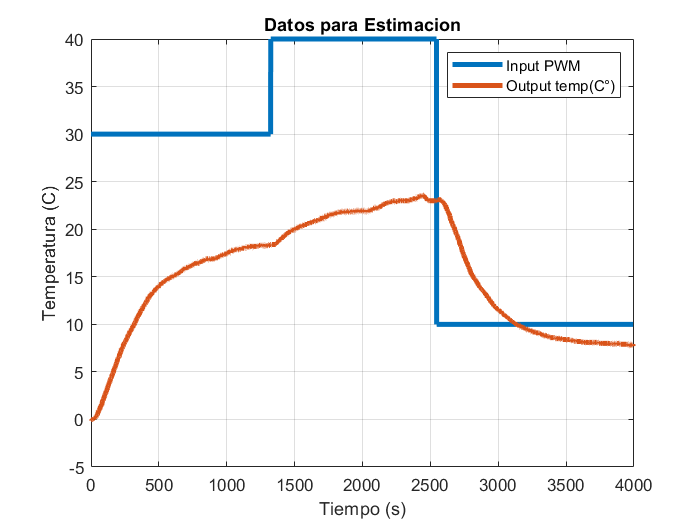

load('systemIdentification_pr6.mat')
plot(ts,us,ts,ys,'linewidth',3),grid
title('Datos de la identificación')
xlabel('Tiempo (s)')
ylabel('Temperatura (C)')
b1=30;
b2=40;
b3=10;

i=1;
while(us(i)<b1)
    i=i+1;
end
x1_start=i;
while(us(i)==b1)
    i=i+1;
end
x1_end=i-1;
%................
while(us(i)<b2)
    i=i+1;
end
x2_start=i;
while(us(i)==b2)
    i=i+1;
end
x2_end=i-1;
%................
while(us(i)<b3)
    i=i+1;
end
x3_start=i;
while(us(i)==b3)
    i=i+1;
end
x3_end=i-1;

ur=us(x1_start:x3_end)';
yr=ys(x1_start:x3_end)';
tr=ts(x1_start:x3_end)';

ut=ur-us(1);
yt=yr-yr(2);
tt=tr-tr(1);

figure(2)
plot(tt,ut,tt,yt,'linewidth',3),grid
title('Datos para Estimacion')
xlabel('Tiempo (s)')
ylabel('Temperatura (C)')
legend('Input PWM','Output temp(C°)')
saveas(gcf,'grafico1_entreno.png')

data_estimacion = iddata(yt,ut,1);

# **MODELO 01:**

Gest =
 
  From input "u1" to output "y1":
                       0.0001776
  exp(-28*s) * -------------------------
               s^2 + 0.1105 s + 0.000294
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                     
Estimated using TFEST on time domain data "data_estimacion".
Fit to estimation data: 88.03%                              
FPE: 0.5275, MSE: 0.5262                                    


Gest = tfest(data_estimacion,2,0,NaN)

%opt = compareOptions;
%opt.InitialCondition = 'z';
%compare(data,Gest,opt);
%set(findall(gca,'Type','Line'),'LineWidth',4);
%grid on

# **MODELO 02:**

sysTF = tfest(data_estimacion,1,0,nan)

sysTF =
 
  From input "u1" to output "y1":
                 0.001621
  exp(-29*s) * ------------
               s + 0.002679
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                     
Estimated using TFEST on time domain data "data_estimacion".
Fit to estimation data: 87.99%                              
FPE: 0.5305, MSE: 0.5297                                    


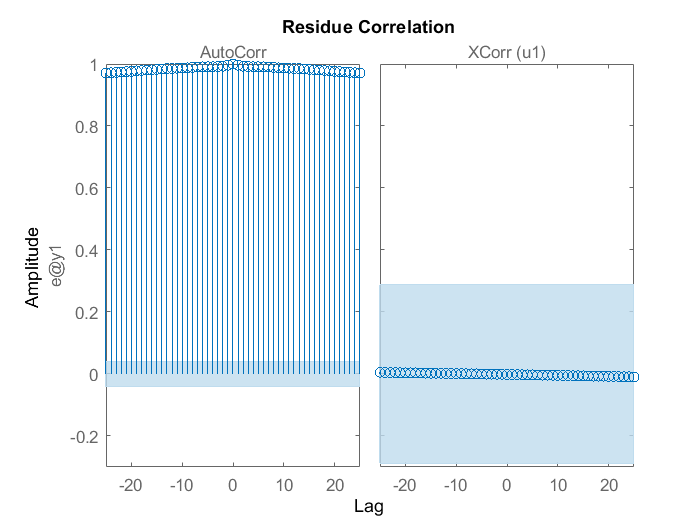

resid(sysTF,data_estimacion);

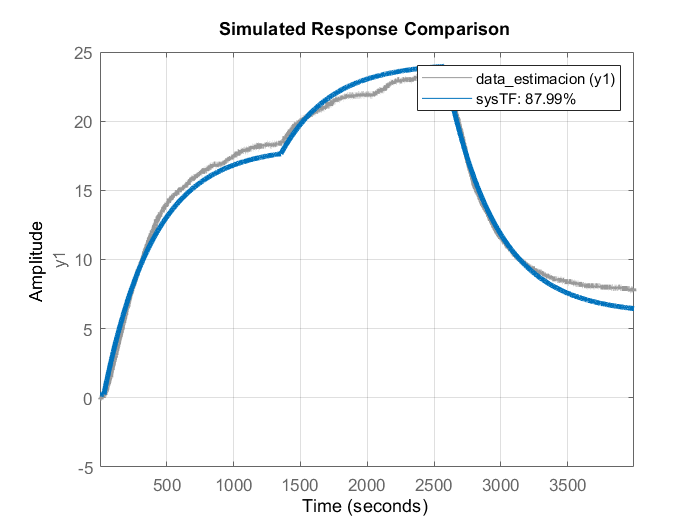

compare(data_estimacion,sysTF)
set(findall(gca,'Type','Line'),'LineWidth',3);
grid on

# **MODELO 03:**

sysInit = idtf(NaN,[1 NaN],'ioDelay',NaN);
sysInit.timeUnit = 'seconds';

sysInit.Structure.num.Value =  1;
sysInit.Structure.num.Minimum = 0;
sysInit.Structure.den.Value = [1 1];
sysInit.Structure.den.Minimum = [0 0];

sysInit.Structure.ioDelay.Value = 0.2;
sysInit.Structure.ioDelay.Minimum = 0;
sysInit.Structure.ioDelay.Maximum = 1;

sysTF_initialized = tfest(data_estimacion,sysInit)

sysTF_initialized =
 
  From input "u1" to output "y1":
                0.001535
  exp(-1*s) * ------------
              s + 0.002519
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                     
Estimated using TFEST on time domain data "data_estimacion".
Fit to estimation data: 87.31%                              
FPE: 0.5928, MSE: 0.5919                                    


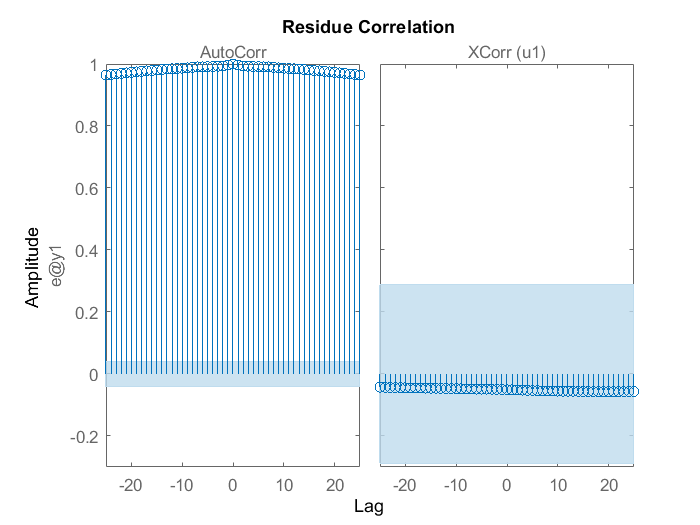

resid(sysTF_initialized,data_estimacion)

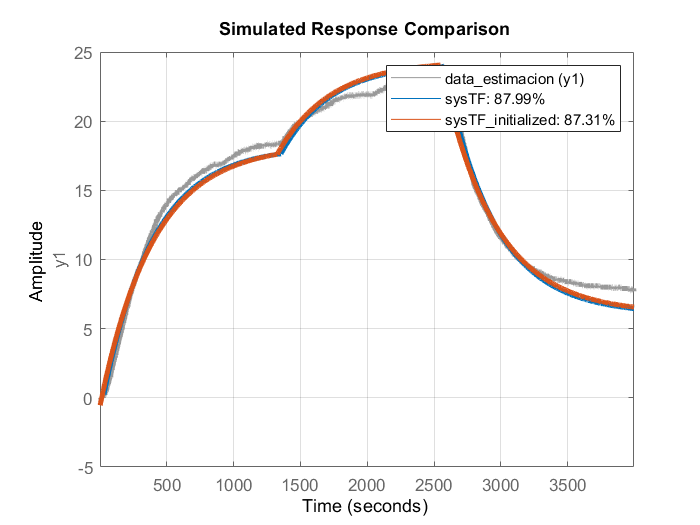

clf
compare(data_estimacion,sysTF,sysTF_initialized)
set(findall(gca,'Type','Line'),'LineWidth',3);
grid on

# **MODELO 04:**

sysP1D = procest(data_estimacion,'P1D')

sysP1D =
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 0.60448                 
       Tp1 = 368.1                   
        Td = 34.923                  
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                       
Estimated using PROCEST on time domain data "data_estimacion".
Fit to estimation data: 88.02%                                
FPE: 0.5286, MSE: 0.5275                                      


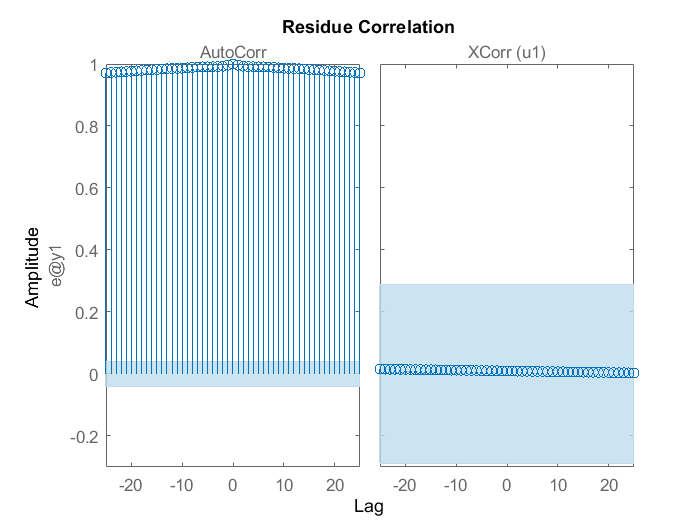

resid(sysP1D,data_estimacion)

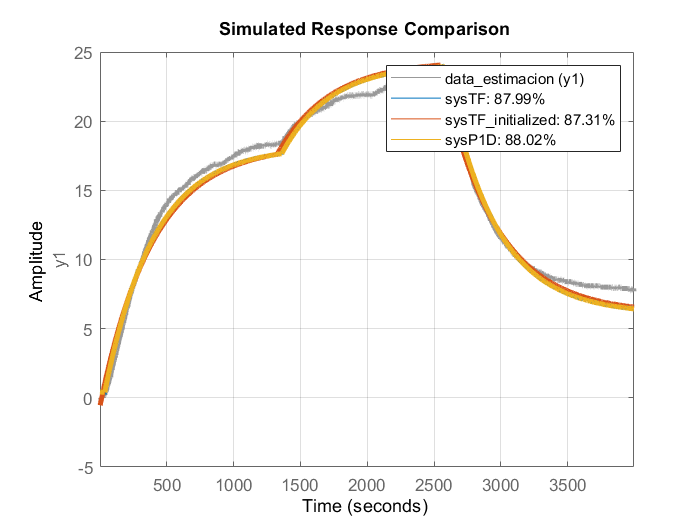

compare(data_estimacion,sysTF,sysTF_initialized,sysP1D)
set(findall(gca,'Type','Line'),'LineWidth',3);
grid on

# **MODELO 05:**

sysInit = idproc('P1D','TimeUnit','seconds');

sysInit.Structure.Kp.Value = 1;
sysInit.Structure.Kp.Minimum = 0.1;
sysInit.Structure.Tp1.Value = 300;
sysInit.Structure.Tp1.Maximum = 400;
sysInit.Structure.Td.Value  = 30;
sysInit.Structure.Td.Minimum = 20;
sysInit.Structure.Td.Maximum = 40;

opt = procestOptions('DisturbanceModel','ARMA1');
sysP1D_noise = procest(data_estimacion,sysInit,opt)

sysP1D_noise =
Process model with transfer function:                
             Kp                                      
  G(s) = ---------- * exp(-Td*s)                     
          1+Tp1*s                                    
                                                     
        Kp = 0.54643                                 
       Tp1 = 396.46                                  
        Td = 40                                      
                                                     
An additive ARMA disturbance model has been estimated
      y = G u + (C/D)e                               
                                                     
      C(s) = s + 0.4258                              
      D(s) = s + 0.0003253                           
                                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 5
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                    

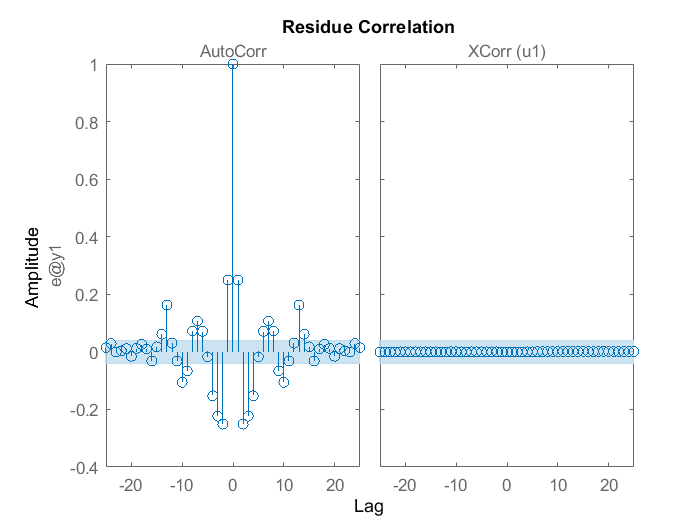

resid(sysP1D_noise,data_estimacion);

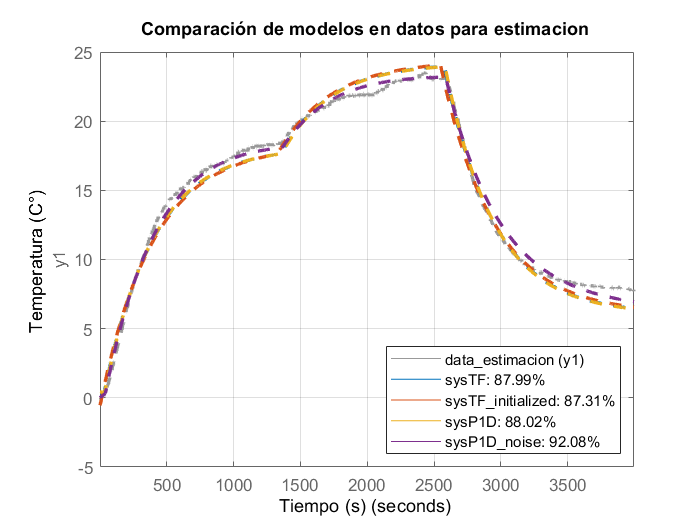

compare(data_estimacion, sysTF, sysTF_initialized, sysP1D, sysP1D_noise);
%set(findall(gca,'Type','Line'),'LineWidth',2);
set(findall(gca,'Type','Line'),'LineStyle','--','LineWidth',2);
xlabel('Tiempo (s)');          % Etiqueta del eje X
ylabel('Temperatura (C°)');            % Etiqueta del eje Y
title('Comparación de modelos en datos para estimacion'); % Título del gráfico
grid on
%lines = findall(gca, 'Type', 'Line'); % Encuentra todas las líneas
%set(lines(1), 'Color', 'g'); % Cambia el color de la primera línea a rojo
legend('Location', 'southeast') % Puedes cambiar 'northeast' por otra opción
saveas(gcf,'grafico2_entreno.png')

%print(gcf,'grafico','-dpdf','-r300')


% Comparar los modelos con los datos experimentales y guardar el handle
%[hFig, hLines] = compare(data, sysTF, sysTF_initialized, sysP1D, sysP1D_noise);
%grid on; hold on;

% Establecer estilos de línea para cada modelo
%set(hLines(1), 'LineStyle', '-',  'LineWidth', 2, 'Color', 'b');  % Línea continua (Datos reales)
%set(hLines(2), 'LineStyle', '--', 'LineWidth', 2, 'Color', 'r');  % Línea punteada larga (sysTF)
%set(hLines(3), 'LineStyle', '-.', 'LineWidth', 2, 'Color', 'm');  % Línea semipunteada (sysTF_initialized)
%set(hLines(4), 'LineStyle', ':',  'LineWidth', 2, 'Color', 'g');  % Línea punteada corta (sysP1D)
%set(hLines(5), 'LineStyle', '--', 'LineWidth', 2, 'Color', 'k');  % Línea punteada larga (sysP1D_noise)

% Mejorar la apariencia
%set(gca, 'FontSize', 14, 'FontWeight', 'bold');
%xlabel('Tiempo (s)', 'FontSize', 16, 'FontWeight', 'bold'); 
%ylabel('Amplitud', 'FontSize', 16, 'FontWeight', 'bold'); 
%title('Comparación de Respuestas Simuladas', 'FontSize', 16, 'FontWeight', 'bold');

% Ajustar leyenda
%legend({'Datos experimentales', 'sysTF', 'sysTF_initialized', 'sysP1D', 'sysP1D_noise'}, ...
%        'Location', 'Best', 'FontSize', 12);

%hold off;


# **ETAPA DE VALIDACION:**

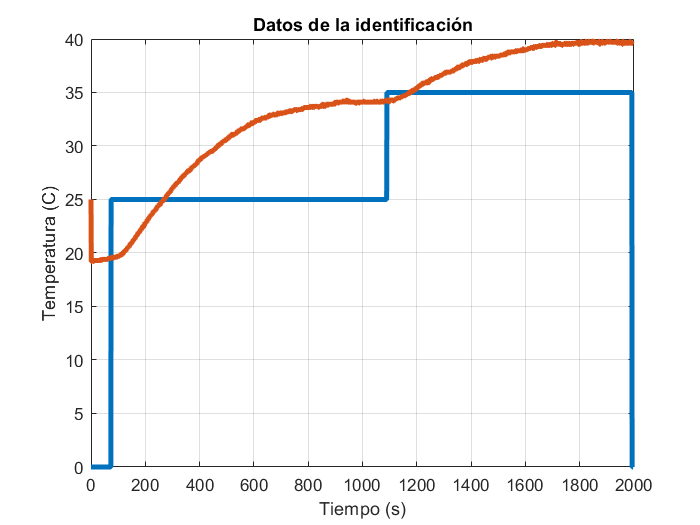

load('systemIdentification_pr3.mat');
plot(ts,us,ts,ys,'linewidth',3),grid;
title('Datos de la identificación');
xlabel('Tiempo (s)');
ylabel('Temperatura (C)');

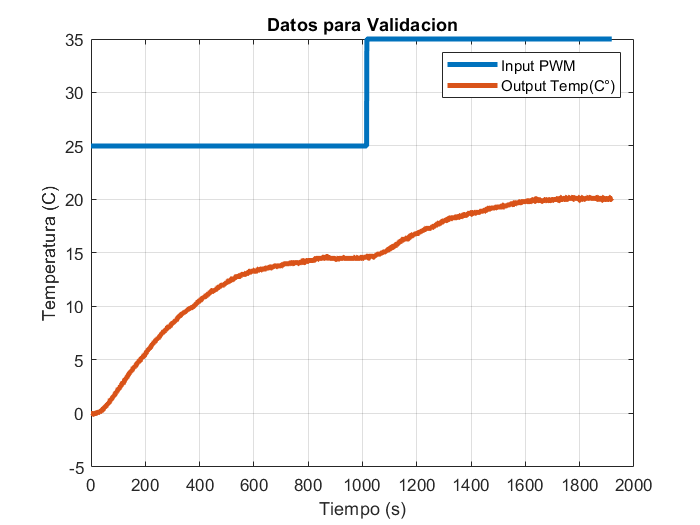

b1=25;
b2=35;

i=1;
while(us(i)<b1)
    i=i+1;
end
x1_start=i;
while(us(i)==b1)
    i=i+1;
end
x1_end=i-1;
while(us(i)<b2)
    i=i+1;
end
x2_start=i;
while(us(i)==b2)
    i=i+1;
end
x2_end=i-1;

ur=us(x1_start:x2_end)';
yr=ys(x1_start:x2_end)';
tr=ts(x1_start:x2_end)';

ut=ur-us(1);
yt=yr-yr(2);
tt=tr-tr(1);

%Graficar escalon Trasladado
figure(2)
plot(tt,ut,tt,yt,'linewidth',3),grid
title('Datos para Validacion')
xlabel('Tiempo (s)')
ylabel('Temperatura (C)')
legend('Input PWM','Output Temp(C°)')
saveas(gcf,'grafico1_validez.png')

data_validacion = iddata(yt,ut,1)

data_validacion =

Time domain data set with 1919 samples.
Sample time: 1 seconds                  
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        


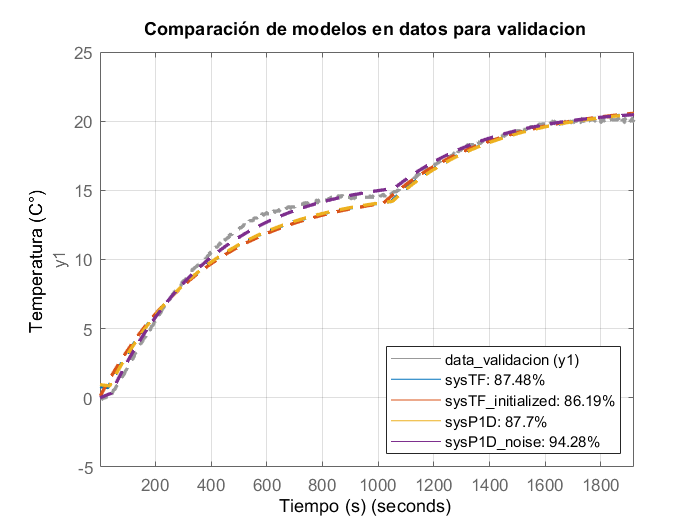

clf
% Comparación de modelos y obtención de los manejadores de gráficos
compare(data_validacion, sysTF, sysTF_initialized, sysP1D, sysP1D_noise);
set(findall(gca,'Type','Line'),'LineStyle','--','LineWidth',2);
xlabel('Tiempo (s)');          % Etiqueta del eje X
ylabel('Temperatura (C°)');            % Etiqueta del eje Y
title('Comparación de modelos en datos para validacion'); % Título del gráfico
legend('Location', 'southeast')
grid on
saveas(gcf,'grafico2_validez.png')